## Forward modeling of 3D gravity anomalies using high-order Gaussian quadrature 

*Copyright © 2024 by Central South University*

*__________________________________________*

`Coding: UTF - 8`

Programme written by Yaokun Yang. 

For more imformation, submit an issue or contact by email

[yangyaokun@csu.edu.cn](http://yangyaokun@csu.edu.cn)

Please read the `README.md` before use.

*__________________________________________*

### 1 Add source and file to PATH

PATH % add path

### 2 Gravity anomaly calculation

First define a array model, and then use the function `CuboidGravity` to calculate the gravity anomaly.

% model = [a1,a2,b1,b2,c1,c2,density]
model = [-50,50,-50,50,-150,-50,2000];
v = CuboidGravity_GaussianQuad(model); 

All functions in this project can be viewed using the `help` directive.

Drawing an image can be done using the following functions.

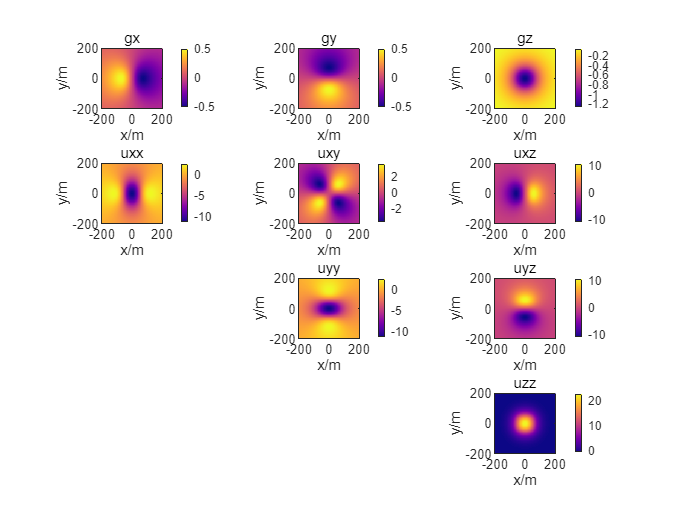

% plot figure
area = ObservationPlane(model);
ImagescGravity(area,v); 

% or use ContourGravity(area,v)

And analytical and numerical solutions are calculated.

% Analytical solutions
a = CuboidGravity_analytical(model,area);
save("Data\Data\CuboidGravityByAnalytical.mat",'a','-mat')

% Numerical solution by integral3
% This function may be slow to compute
% it is recommended to fetch data from \Data.
I = CuboidGravity_integral3(model,area); 
save("Data\Data\CuboidGravityByIntegral3.mat",'I','-mat')

### 3 Comparison error

The analytical solution is calculated and the error is compared.

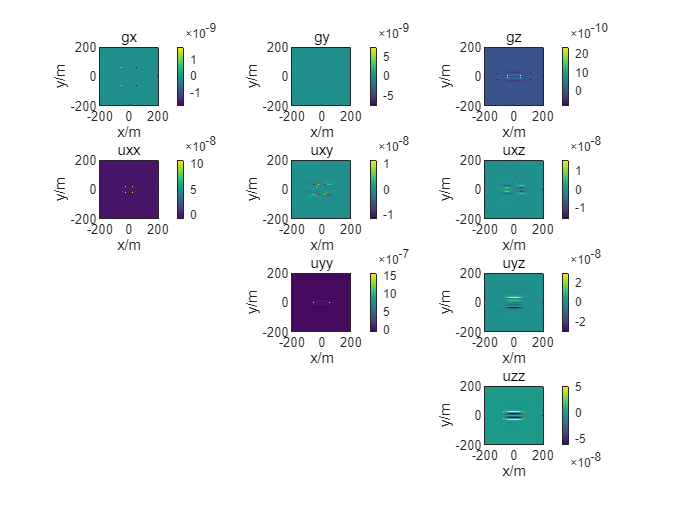

% Calculation error
E = ErrorCompare(I,a);
ImagescGravity(area,E,'viridis');

save("Data\Data\ErrorByIntegral3.mat",'E','-mat')

18 * 18 * 18 Lobatto quaduature

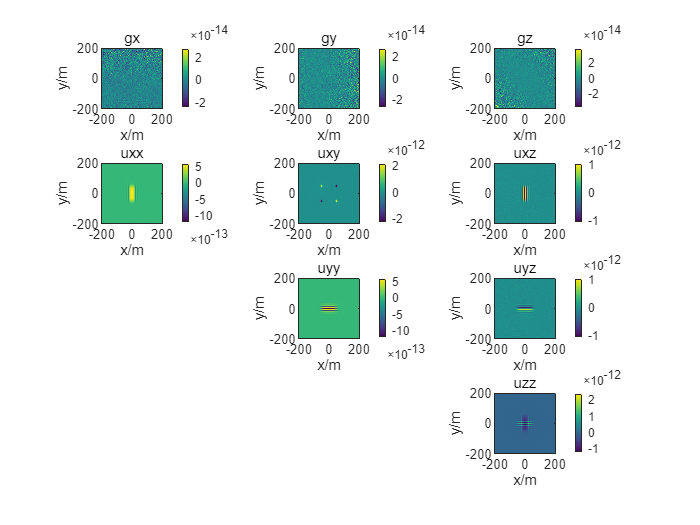

% Number of Gaussian points
n = 18*ones(1,3);
v = CuboidGravity_GaussianQuad(model,area,'method','l','n',n); 
save("Data\Data\CuboidGravityByLobatto.mat",'v','-mat')

E = ErrorCompare(v,a);
ImagescGravity(area,E,'viridis');

save("Data\Data\ErrorByLobatto.mat",'E','-mat')

18 * 18 * 18 Radau quaduature

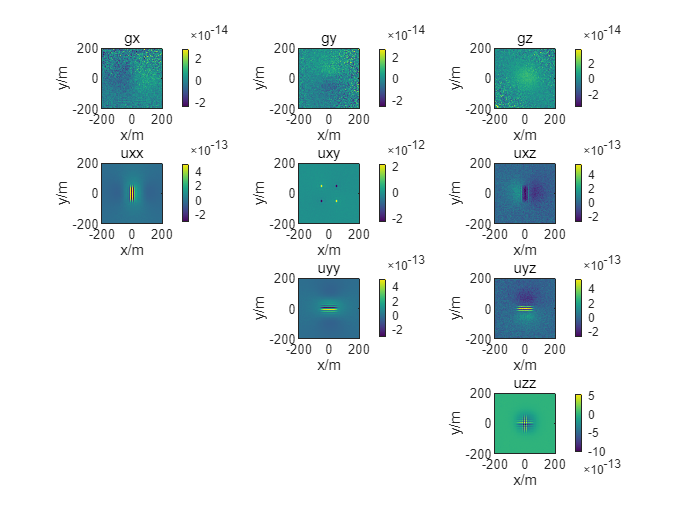

n = 18*ones(1,3);
v = CuboidGravity_GaussianQuad(model,area,'method','r','n',n); 
save("Data\Data\CuboidGravityByRadau.mat",'v','-mat')

E = ErrorCompare(v,a);
ImagescGravity(area,E,'viridis');

save("Data\Data\ErrorByRadau.mat",'E','-mat')

18 * 18 * 18 Gauss-Legendre quaduature

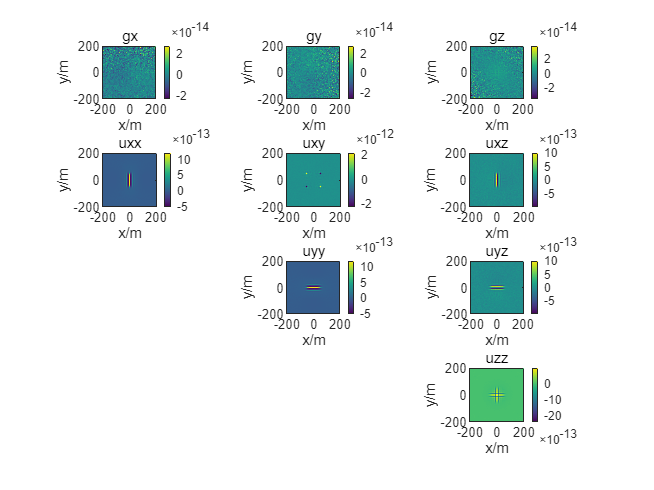

n = 18*ones(1,3);
v = CuboidGravity_GaussianQuad(model,area,'method','gl','n',n); 
save("Data\Data\CuboidGravityByGaussLegendre.mat",'v','-mat')

E = ErrorCompare(v,a);
ImagescGravity(area,E,'viridis');

save("Data\Data\ErrorByGaussLegendre.mat",'E','-mat')

18 * 18 * 18 Gauss-Chebyshev quaduature

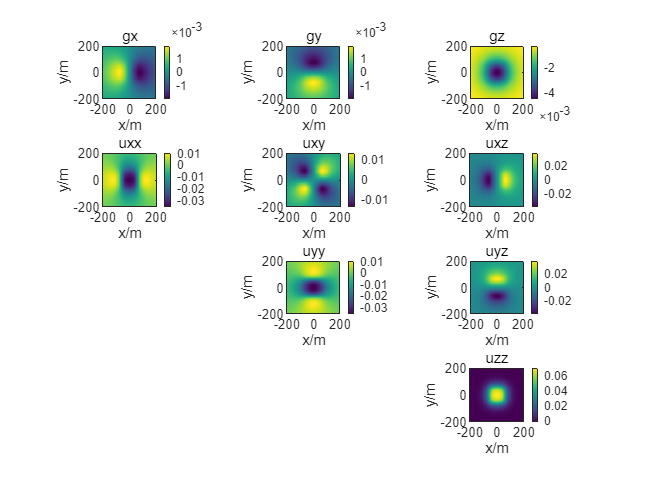

n = 18*ones(1,3);
v = CuboidGravity_GaussianQuad(model,area,'method','gc','n',n); 
save("Data\Data\CuboidGravityByGaussChebyshev.mat",'v','-mat')

E = ErrorCompare(v,a);ImagescGravity(area,E,'viridis');

save("Data\Data\ErrorByGaussChebyshev.mat",'E','-mat')